clc
clear
close all

fs = 10000;          % Sampling frequency
t = 0:1/fs:0.1;      % Time vector

fm = 50;             % Message frequency
fc = 500;            % Carrier frequency

Am = 1;              % Message amplitude
Ac = 1;              % Carrier amplitude

m = Am*cos(2*pi*fm*t);     % Message signal
c = Ac*cos(2*pi*fc*t);     % Carrier signal

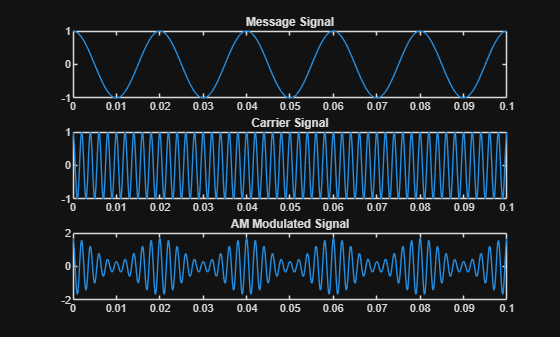

mu = 0.7;  % modulation index

s_am = Ac*(1 + mu*m).*cos(2*pi*fc*t);

figure
subplot(3,1,1)
plot(t,m)
title('Message Signal')

subplot(3,1,2)
plot(t,c)
title('Carrier Signal')

subplot(3,1,3)
plot(t,s_am)
title('AM Modulated Signal')

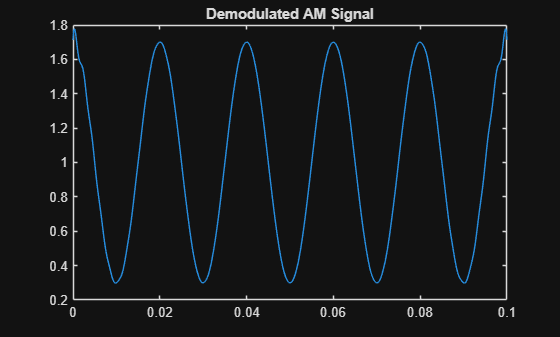

demod = abs(hilbert(s_am));

figure
plot(t,demod)
title('Demodulated AM Signal')

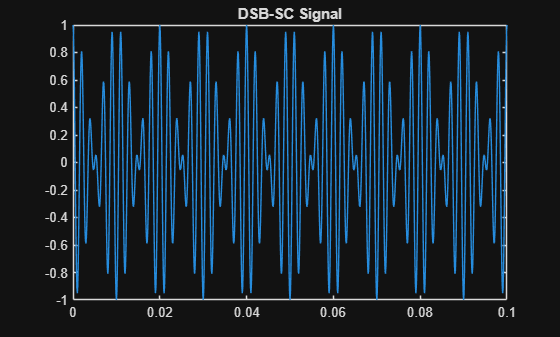

s_dsbsc = m .* cos(2*pi*fc*t);

figure
plot(t,s_dsbsc)
title('DSB-SC Signal')

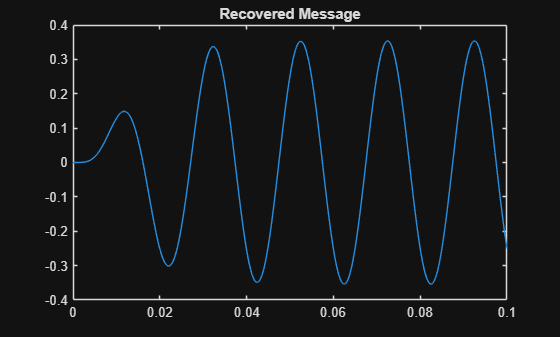

demod_dsb = s_dsbsc .* cos(2*pi*fc*t);

[b,a] = butter(5, fm/(fs/2));    % Low pass filter
recovered = filter(b,a,demod_dsb);

figure
plot(t,recovered)
title('Recovered Message')

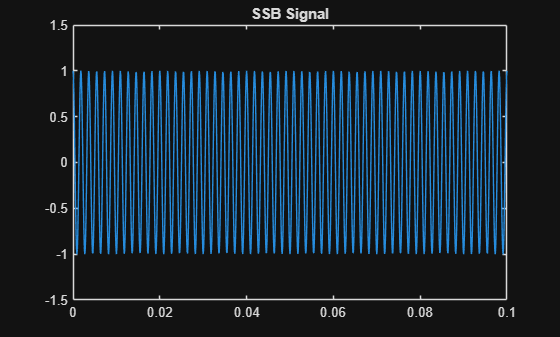

mh = imag(hilbert(m));  % Hilbert transform

ssb = m.*cos(2*pi*fc*t) - mh.*sin(2*pi*fc*t);

figure
plot(t,ssb)
title('SSB Signal')

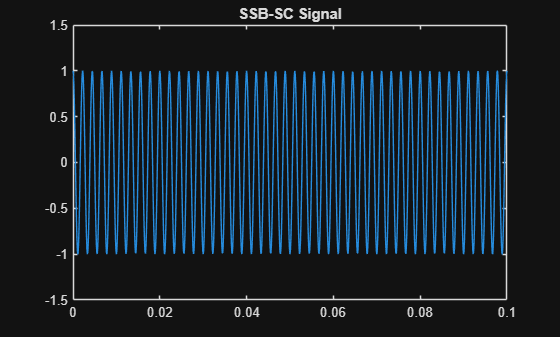

ssb_sc = m.*cos(2*pi*fc*t) + mh.*sin(2*pi*fc*t);

figure
plot(t,ssb_sc)
title('SSB-SC Signal')

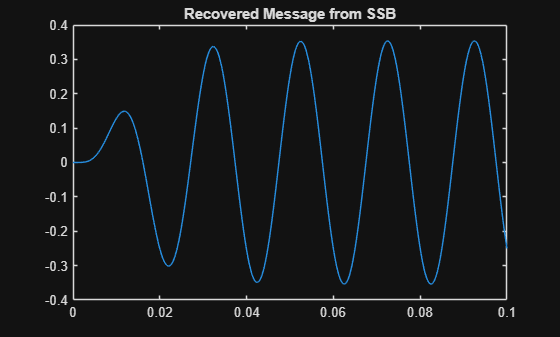

demod_ssb = ssb_sc .* cos(2*pi*fc*t);

[b,a] = butter(5, fm/(fs/2));
rec_ssb = filter(b,a,demod_ssb);

figure
plot(t,rec_ssb)
title('Recovered Message from SSB')

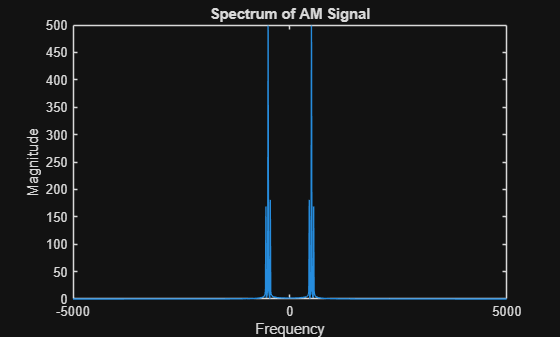

n = length(t);
f = (-n/2:n/2-1)*(fs/n);

S = fftshift(abs(fft(s_am)));

figure
plot(f,S)
title('Spectrum of AM Signal')
xlabel('Frequency')
ylabel('Magnitude')